clear all

folder = "1-sensor_thickness"

folder = "1-sensor_thickness"


addpath(folder);

% voltage = 2.5;
% 
% thickness = 0.5;
% 
% speaker = 'lg'; % 'lg' or 'sm'

function max_coh = sensor_alignment(voltage, thickness, speaker)

acc_file = strcat('acc_',num2str(thickness),'mm_',num2str(voltage),'V_',speaker,'.txt');

ind_file = strcat('ind_',num2str(thickness),'mm_',num2str(voltage),'V_',speaker,'.csv');


%% read acc data
% Open the file for reading
fid = fopen(acc_file, 'r');
if fid == -1
    error('File cannot be opened.');
end

% Initialize arrays for valid data
timeSecs = [];
value1  = [];
value2  = [];

% Define a regular expression pattern.
% This pattern looks for:
%  - One or more digits for hours, minutes, seconds, and milliseconds.
%  - The literal " -> " between the time and the two numeric values.
%  - Two floating-point numbers separated by a comma.
pattern = '^(\d+):(\d+):(\d+):(\d+)\s*->\s*(-?\d+\.\d+),(-?\d+\.\d+)$';

while ~feof(fid)
    tline = fgetl(fid);

    % Use regexp to see if the line matches the complete pattern.
    tokens = regexp(tline, pattern, 'tokens');

    if ~isempty(tokens)
        % Convert token strings to numbers.
        nums = cellfun(@str2double, tokens{1});
        h  = nums(1);
        m  = nums(2);
        s  = nums(3);
        ms = nums(4);
        v1 = nums(5);
        v2 = nums(6);

        % Convert the time into seconds.
        timeInSec = h*3600 + m*60 + s + ms/1000;

        timeInMs = timeInSec;

        % Append to our arrays
        timeSecs(end+1, 1) = timeInMs;
        value1(end+1, 1)  = v1;
        value2(end+1, 1)  = v2;
    end
    % If tokens is empty, the line is incomplete or doesn’t match the format.
    % In that case, it is automatically disregarded.
end

% Close the file
fclose(fid);

timeSecs = timeSecs - timeSecs(1);

% Display the results (as a table for clarity)
acc_data = table(timeSecs, value1, value2);

%% read ind data

ind_data = readtable(ind_file);

deltaTimes = ind_data{:,'evmSampleDeltaMs'};  % extract the delta time column

% Set a threshold to detect a "big" delta that signals a new batch.
% In your data, the big delta values (that mark a batch) are >> 1 (ms).
threshold = 1;

% Identify the starting indices for each batch.
batchStartIdx = find(deltaTimes >= threshold);
N = length(deltaTimes);

% We'll create an array to hold the computed absolute timestamps.
absTime = zeros(N,1);

% --- Process Batches 2 to End ---
% We skip the first batch for now (because its big delta is not reliable).
% For batches 2 onward, we use the same idea as before:
% For a batch that starts at a big delta value, evenly distribute that delta
% across the points in the batch and add the cumulative time.
%
% For batch 2, we define the starting time T0 arbitrarily (e.g. 0).
% For subsequent batches, T0 is updated to be the last timestamp from the previous batch.
if length(batchStartIdx) < 2
    error('Not enough batches to compute average sample interval.');
end

T0 = 0;  % initialize cumulative time
for b = 2:length(batchStartIdx)
    startIdx = batchStartIdx(b);
    if b < length(batchStartIdx)
        endIdx = batchStartIdx(b+1) - 1;
    else
        endIdx = N;
    end

    nPoints = endIdx - startIdx + 1;
    bigDelta = deltaTimes(startIdx);

    % Evenly distribute the big delta across the nPoints.
    if nPoints > 1
        dt_batch = linspace(0, bigDelta, nPoints);
    else
        dt_batch = bigDelta;
    end

    absTime(startIdx:endIdx) = T0 + dt_batch;
    T0 = absTime(endIdx);  % update cumulative time for next batch
end

% --- Compute Average Sampling Interval from Batches 2+ ---
allDt = [];
for b = 2:length(batchStartIdx)
    startIdx = batchStartIdx(b);
    if b < length(batchStartIdx)
        endIdx = batchStartIdx(b+1) - 1;
    else
        endIdx = N;
    end

    if (endIdx - startIdx) >= 1
        allDt = [allDt; diff(absTime(startIdx:endIdx))];
    end
end

avgDt = mean(allDt);

% --- Process Batch 1 using Back-Extrapolation ---
% Batch 1 is from batchStartIdx(1) to (batchStartIdx(2)-1).
firstBatchStart = batchStartIdx(1);
firstBatchEnd   = batchStartIdx(2) - 1;
n_first = firstBatchEnd - firstBatchStart + 1;

% Assume that the first sample of batch 2 is correctly computed as a reference.
T_batch2_start = absTime(batchStartIdx(2));

% We want the last sample of batch 1 to be exactly one avgDt before T_batch2_start.
% Then, we assign batch 1 timestamps evenly spaced backwards.
% For example, if there are N₁ samples, assign:
%    T_batch1 = linspace( T_batch2_start - n_first*avgDt, T_batch2_start - avgDt, n_first)
absTime(firstBatchStart:firstBatchEnd) = linspace(T_batch2_start - n_first*avgDt, T_batch2_start - avgDt, n_first)';

absTime = absTime - absTime(1);

ind_data.absTime = absTime;





acc_data = rmmissing(acc_data);
ind_data = rmmissing(ind_data);

acc_data.Properties.VariableNames = {'time', 'x_accel', 'y_accel'};

acc_data.time_diff = [0; diff(acc_data.time)];
acc_data = acc_data(9:end-100, :);

ind_data.time_diff = [0; diff(ind_data.absTime)];

acc_rate = mean(acc_data.time_diff)
acc_std = std(acc_data.time_diff)
acc_Fs =  1000/acc_rate
ind_rate = mean(ind_data.time_diff)
int_std = std(ind_data.time_diff)
ind_Fs = 1000/ind_rate


acc_time_span = acc_data.time(end) - acc_data.time(1)
ind_time_span = ind_data.absTime(end) ./1000


% plot(acc_data.x_accel)
[x_max, x_idx] = max(acc_data.x_accel)
figure;
plot(acc_data.y_accel)
[y_max, y_idx] = max(acc_data.y_accel)
figure;
plot(ind_data.DATA0_uH)
[ind_max, ind_idx] = max(ind_data.DATA0_uH)



sync_acc_data = acc_data((y_idx + floor(5000/acc_rate)):end,:);
sync_ind_data = ind_data((ind_idx + floor(5000/ind_rate)):end, :);
% sync_ind_data = ind_data(400:900, :);
% sync_acc_data.norm_z_accel = (sync_acc_data.z_accel - mean(sync_acc_data.z_accel)) / std(sync_acc_data.z_accel)
%
% vel = diff(sync_acc_data.norm_z_accel) ./ sync_acc_data.time_diff(2:end);
% disp = diff(vel) ./ sync_acc_data.time_diff(3:end);

% plot(disp)
% title('Displacement')




% rs_acc = resample(sync_acc_data.y_accel, 300, round(acc_Fs));
% 
% rs_ind = resample(sync_ind_data.DATA0_uH, 300, round(ind_Fs));

rs_acc_time = acc_data.time(1):1/500:acc_data.time(end);
rs_ind_time = ind_data.absTime(1)/1000.0:0.005:ind_data.absTime(end)/1000.0;

rs_acc = interp1(acc_data.time,acc_data.y_accel,rs_acc_time','spline');
rs_ind = interp1(ind_data.absTime/1000,ind_data.DATA0_uH,rs_ind_time','spline');


% s_idx = 5*300;
% e_idx = 1.5*300;
% rs_acc = rs_acc(s_idx:e_idx,:);
% rs_ind = rs_ind(s_idx:e_idx,:);


% plot(ds_ind_data.DATA2_uH)
% plot(ds_acc_data.x_accel)
%
figure;
plot(rs_ind)
% plot(rs_x)
figure;
plot(rs_acc)
% plot(rs_z)


fs = 500;           % Sample rate in Hz (adjust as needed)
cutoff_freq = 10;    % Cutoff frequency in Hz
filter_order = 3;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');

lp_y= filtfilt(b, a, rs_acc);
lp_ind= filtfilt(b, a, rs_ind);

mf_y = smooth(lp_y,10, 'moving');
mf_ind = smooth(lp_ind,10, 'moving');

filtered_y = smooth(mf_y,11,'sgolay');
filtered_ind = smooth(mf_ind,11,'sgolay');

% plot(filtered_x)
figure;
plot(lp_y)

figure;
plot(lp_ind)

figure;
plot(filtered_y)

figure;
plot(filtered_ind)


new_y = resample(filtered_y, 300, acc_Fs*round(500/acc_Fs));

new_ind = resample(filtered_ind, 300, ind_Fs*round(500/ind_Fs));

normalized_sensor = (new_ind - mean(new_ind)) / std(new_ind);
normalized_accel = (new_y - mean(new_y)) / std(new_y);

norm_vel = diff(normalized_sensor) ./ (1/fs);
norm_acc = diff(norm_vel) ./ (1/fs);

trimmed_accel = normalized_accel(3:end);

% plot(norm_acc)
% title("Induction accel")
% 
% 
% plot(normalized_accel)
% title("Accel")
% 
% plot(normalized_sensor)
% title("Inductor")

% Calculate cross-correlation
[correlation, lags] = xcorr(normalized_accel(3:end), norm_acc, 'coeff');

% Find maximum correlation and its position
[max_corr, max_idx] = max(correlation);
lag_at_max = lags(max_idx);

% Plot results
figure;
plot(lags, correlation);
xlabel('Lag');
ylabel('Correlation');
title(['Maximum correlation: ', num2str(max_corr), ' at lag ', num2str(lag_at_max)]);


% Calculate coherence
[cxy, f] = mscohere(norm_acc, normalized_accel(3:end));


% Plot coherence
figure;
plot(f, cxy);
xlabel('Frequency (Hz)');
ylabel('Magnitude-Squared Coherence');
title('Coherence between Sensor and Acceleration Data');

% Find maximum coherence and corresponding frequency
[max_coh, max_idx] = max(cxy);
freq_at_max = f(max_idx);


% Interpret the coherence strength
if max_coh >= 0.8
    coh_quality = "Very strong coherence";
elseif max_coh >= 0.6
    coh_quality = "Strong coherence";
elseif max_coh >= 0.4
    coh_quality = "Moderate coherence";
elseif max_coh >= 0.2
    coh_quality = "Weak coherence";
else
    coh_quality = "Very weak coherence";
end

disp(['Maximum coherence: ', num2str(max_coh), ' at frequency ', num2str(freq_at_max), ' Hz']);
disp(['Coherence quality: ', coh_quality]);


end


acc_rate = 0.0096

acc_std = 0.0034

acc_Fs = 1.0431e+05

ind_rate = 2.5864

int_std = 1.0810

ind_Fs = 386.6333

acc_time_span = 39.7370

ind_time_span = 43.6822

x_max = -491.4600

x_idx = 1

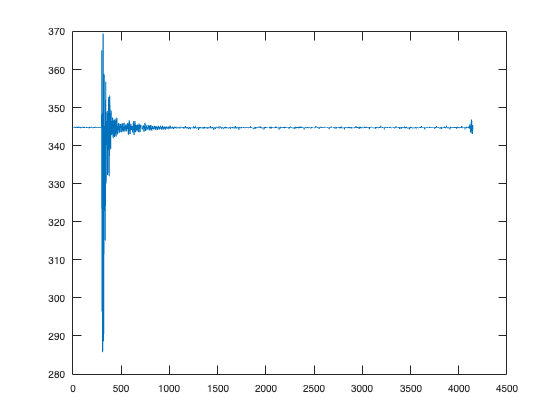

y_max = 369.4950

y_idx = 313

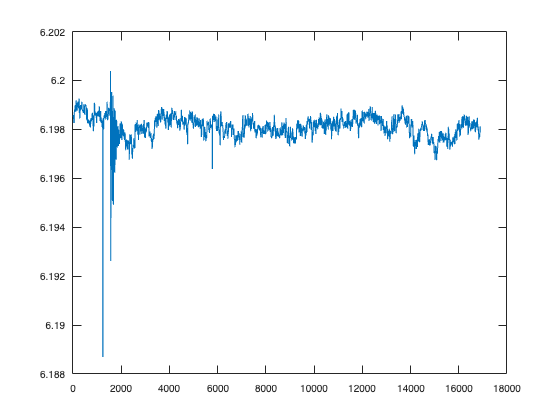

ind_max = 6.2004

ind_idx = 1552

Error using matlab.internal.math.interp1
Sample points must be unique.

Error in interp1 (line 188)
        VqLite = matlab.internal.math.interp1(X,V,method,method,Xqcol);

Error in data_process>sensor_alignment (

sm_voltage = 2:0.5:3.5;
sm_voltage = [1.7, sm_voltage];
lg_voltage = 5:0.5:5.5;

all_thickness = 2;
all_speaker = ["lg"];

data2plot = [];

for j = 1:length(all_thickness)
    thickness = all_thickness(j);
    for i = 1:length(all_speaker)
        speaker = all_speaker(i);
        if strcmp(speaker,'sm')
            all_voltage = sm_voltage;
        else
            all_voltage = lg_voltage;
        end
        for k = 1:length(all_voltage)
            voltage = all_voltage(k);
            max_coh = sensor_alignment(voltage, thickness, speaker);
            data2plot = [data2plot;speaker,thickness,voltage,max_coh];
        end
    end
end


idx_lg = strcmp(data2plot(:,1), 'lg');
idx_sm = strcmp(data2plot(:,1), 'sm');

lg_data = data2plot(idx_lg,:);
sm_data = data2plot(idx_sm,:);

function plotGrid(data,titleWord)

data = str2double(data);
% Suppose 'data' is an N-by-3 matrix: [x, y, intensity]
x = data(:,1);
y = data(:,2);
intensity = data(:,3);

% Get unique grid values
xi = unique(x);
yi = unique(y);

% Check that the grid size matches the data length
if numel(xi)*numel(yi) ~= numel(x)
    error('Data does not appear to be on a regular grid.');
end

% Reshape intensity into a matrix. Here we assume that the data is
% ordered so that intensity varies fastest along x and then y.
I = reshape(intensity, numel(yi), numel(xi));

% Plot the heatmap. 'imagesc' will display the matrix as an image.
figure;
imagesc(xi', yi', I);
set(gca, 'YDir','normal'); % Ensures y-axis is in the correct orientation
colorbar;
xlabel('X Axis');
ylabel('Y Axis');
title(titleWord);
end

plotGrid(lg_data(:,2:4),'large');
plotGrid(sm_data(:,2:4),'small');
